# 一、训练YOLO v2用于检测车辆

## 1.1 导入数据

Load the training data for vehicle detection into the workspace.

clear;clc;
% 第一次使用需要按照B站视频自己进行标注数据，并把它保存为gTruth，否则会出错。
load('gTruth.mat');                               %标记的gTruth
trainingfiles = gTruth.DataSource.Source;         %图像位置
traininglabel = gTruth.LabelData;                 %图像标签

Create an imageDatastore using the files from the table.

imgfiles = imageDatastore(trainingfiles);

Create a boxLabelDatastore using the label columns from the table.

imglabel = boxLabelDatastore(traininglabel);

Combine the datastores.

ds = combine(imgfiles, imglabel);

## 1.2 加载Yolov2模型

Load a preinitialized YOLO v2 object detection network.

net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph;
lgraph.Layers;

## 1.3 设置训练参数

options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',100,...
          'Shuffle','never',...
          'VerboseFrequency',10,...
          'CheckpointPath',tempdir);

## 1.4 训练Yolov2模型

Train the YOLO v2 network.

[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Car

在单 GPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　　　　　６．６４　｜　　　　４４．１　｜　　０．００１０　｜
｜　　　４　｜　　　１０　｜　　　　　００：００：０１　｜　　　　　　　１．５６　｜　　　　　２．４　｜　　０．００１０　｜
｜　　　７　｜　　　２０　｜　　　　　００：００：０３　｜　　　　　　　１．１９　｜　　　　　１．４　｜　　０．００１０　｜
｜　　１０　｜　　　３０　｜　　　　　００：００：０４　｜　　　　　　　０．８６　｜　　　　　０．７　｜　　０．００１０　｜
｜　　１４　｜　　　４０　｜　　　　　００：００：０６　｜　　　　　　　０．５７　｜　　　　　０．３　｜　　０．００１０　｜
｜　　１７　｜　　　５０　｜　　　　　００：００：０７　｜　　　　　　　０．５０　｜　　　　　０．２　｜　　０．００１０　｜
｜　　２０　｜　　　６０　｜　　　　　００：００：０９　｜　　　　　　　０．６８　｜　　　　　０．５　｜　　０．００１０　｜
｜　　２４　｜　　　７０　｜　　　　　００：００：１０　｜　　　　　　　０．５２　｜　　　　　０．３　｜　　０．００１０　｜
｜　　２７　｜　　　８０　｜　　　　　００：００：１２　｜　　　　　　　０．４６　｜　　　　　０．２　｜　　０．００１０　｜
｜　　３０　｜　　　９０　｜　　　　

## 1.5 绘制训练模型损失曲线

You can verify the training accuracy by inspecting the training loss for each iteration.

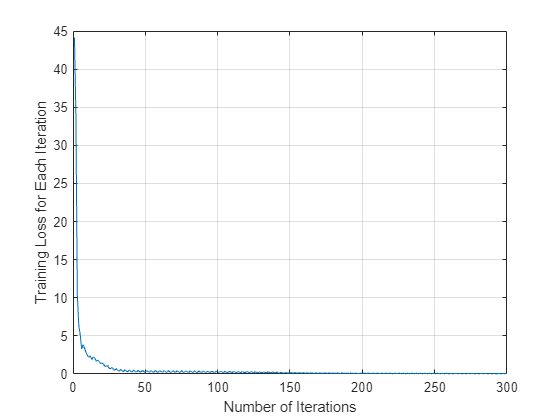

figure
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss for Each Iteration')

## 1.6 保存模型

save("YoloModel.mat","detector");
% save("TrainedInfo.mat","info");